**Conditional probability for the MU to stay withing the illuminated area vs radius: **$f_{\tau_j;r_\mathrm{in}}}$

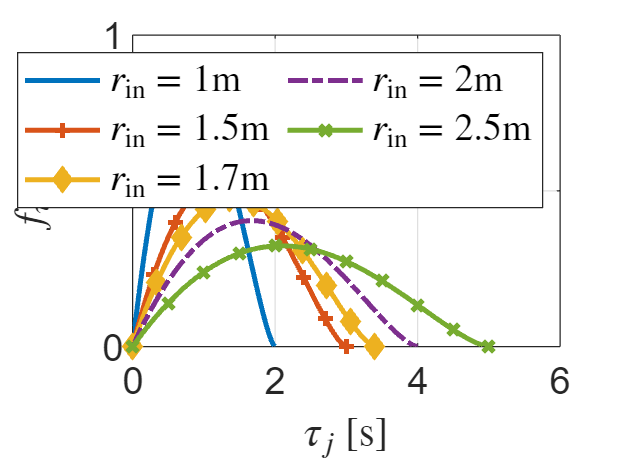

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
r=1:step:length(r_inner);
for j=1:length(r)
    tau_j=(0:length(f_tau_j{r(j)})-1)*delta_tau_j;
    plot(tau_j,f_tau_j{r(j)},marker{j},'Color',color{j},'LineWidth',2,...
        'MarkerEdgeColor',color{j},'MarkerFaceColor',color{j},'MarkerIndices',1:round(length(tau_j)/10):length(tau_j));hold on;
end

grid on;
hold off %to close the canvas

legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

xlabel('$\tau_j$ [s]','Interpreter','latex');
ylabel('$f_{\tau_j;r_\mathrm{in}}$','Interpreter','latex');
set(gca,'FontSize',fontsize);
saveas(gcf, './results/f_tau_j.fig');
saveas(gcf, './results/f_tau_j.svg');

**Conditional probability for the MU to stay withing the illuminated area vs number of jumps: **$f_{T_\mathrm{out}}(t_\mathrm{out}|j)=
    \underbrace{f_{\tau_j;r_\mathrm{in}}\ast \cdots \ast f_{\tau_j;r_\mathrm{in}}}_{j}\big|_{\tau_j=t_\mathrm{out}}$

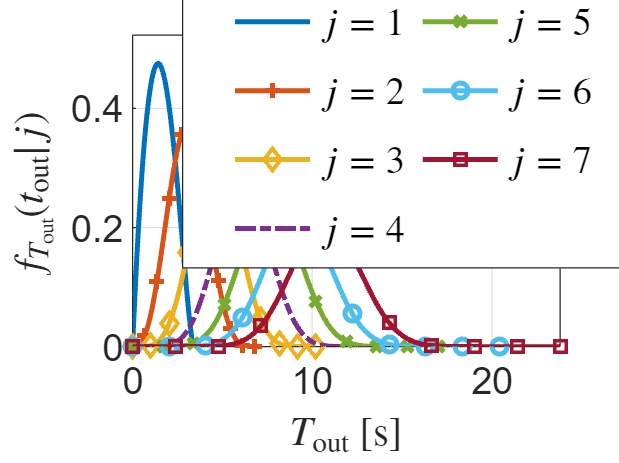

r_select=3;
figure;
total_curves=7;
step=ceil(J/total_curves);
r=1:step:J;

for j=1:total_curves
    tau=(0:length(f_tau{r_select,r(j)})-1)*delta_tau_j;
    plot(tau,f_tau{r_select,r(j)},marker{j},'Color',color{j},...
        'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
end
grid on;

legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$j=',num2str(r(m),2),'$');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

legend("Position", [0.44859,0.5482,0.44286,0.3619]);
xlabel('$T_\mathrm{out}$ [s]','Interpreter','latex');
ylabel('$f_{T_\mathrm{out}}(t_\mathrm{out}|j)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 tau(end) 0 1.1*max(f_tau{r_select,1})]);
saveas(gcf, './results/N_fold_f_tau.fig');
saveas(gcf, './results/N_fold_f_tau.svg');

**Probability to find the user within the illuminated area**

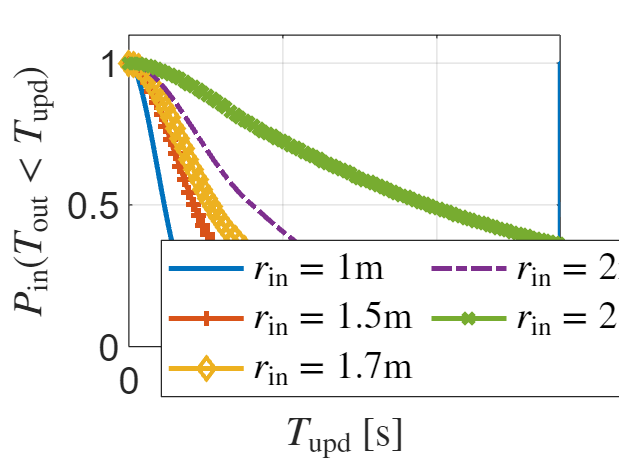

figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
% r=1:step:length(r_inner);
r=1:length(r_inner);
for j=1:1:length(r)
    tau=(0:length(P_r_in(r(j),:))-1)*delta_tau_j;
    plot(tau,P_r_in(r(j),:),marker{j},'LineWidth',2,'Color',color{j},'LineWidth',2,...
        'MarkerIndices',1:3000:length(tau)); hold on;
end

legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

legend("Position", [0.48163,0.22027,0.40624,0.18333]);

grid on;
xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$P_\mathrm{in}(T_\mathrm{out}<T_{\mathrm{upd}})$','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 tau(length(P_T_out_j{1,1})-1) 0 1.1*max(max(P_fh_out))]);
saveas(gcf, './results/P_r_in.fig');
saveas(gcf, './results/P_r_in.svg');

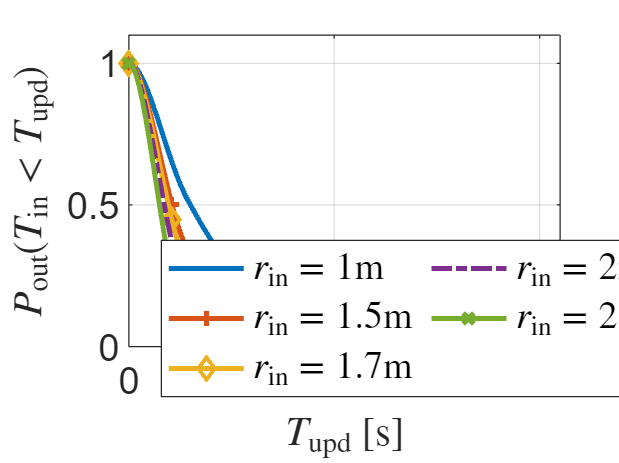


figure;
total_curves=7;
step=ceil(length(r_inner)/total_curves);
% r=1:step:length(r_inner);
r=1:length(r_inner);

for j=1:1:length(r)
    tau=(0:length(P_r_out(r(j),:))-1)*delta_tau_j;
    plot(tau,P_r_out(r(j),:),marker{j},'LineWidth',2,'Color',color{j},'LineWidth',2,'MarkerIndices',1:round(length(tau)/10):length(tau)); hold on;
end


legend_text=cell(1,length(r));
for m=1:floor(length(r))
  legend_text{m}=strcat('$r_\mathrm{in}=',num2str(r_inner(r(m)),2),'$m');
end

legend({legend_text{:}},...
    'Location','northeast','NumColumns',2,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html
grid on;
hold off %to close the canvas

legend("Position", [0.48163,0.22027,0.40624,0.18333]);

grid on;
xlabel('$T_\mathrm{upd}$ [s]','Interpreter','latex');
ylabel('$P_\mathrm{out}(T_\mathrm{in}<T_{\mathrm{upd}})$','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 tau(length(P_T_in_j{1,1})-1) 0 1.1]);
saveas(gcf, './results/P_r_out.fig');
saveas(gcf, './results/P_r_out.svg');